### Robust Control

## Assignment II: Multi-variable mixed-sensitivity control.

Load the plant model.

clear; clc; close all;

load assignment_data_sc42145
sys = ss(A,B,C,D);
G_MIMO = tf(sys);
G = G_MIMO(:,1:2); % Check if they want us to do this

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



#### Question 1 

Compute the RGA for $$\omega=0$$ and $$\omega = 0.4\times2\times \pi$. What can you conclude?

RGA = @(G, omega) evalfr(G, omega).*pinv(evalfr(G, omega)).';

disp('RGA (omega = 0):');

RGA (omega = 0):


disp(RGA(G, 0))

     -0.65542       1.6554
       1.6554     -0.65542




disp('RGA (omega = 0.8*pi):');

RGA (omega = 0.8*pi):


disp(RGA(G, 0.8*pi))

    -0.091779       1.0918
       1.0918    -0.091779



**Observations**

- Diagonal entries are negative.

- Diagonal entries are a lot smaller than the anti-diagonal entries.

- Usually the positive pairings closest to one are desirable for control, as such it seems we want to pair both channels with each other, so u1 to y2 and u2 to y1.

- There are no large (> 10) entries.

#### Question 2 

Compute the zeros and poles of the system.

disp('Zeros of the plant')

Zeros of the plant


G_zeros = tzero(G);
disp(G_zeros)

    -0.083202 +     3.2936i
    -0.083202 -     3.2936i
   -0.0078121 +     1.2358i
   -0.0078121 -     1.2358i
     -0.41041 +          0i
    -0.010567 +    0.20223i
    -0.010567 -    0.20223i




disp('Poles of the plant')

Poles of the plant


G_poles = pole(G);
disp(G_poles)

    -0.083202 +     3.2936i
    -0.083202 -     3.2936i
     -0.41041 +          0i
    -0.010567 +    0.20223i
    -0.010567 -    0.20223i
    -0.083202 +     3.2936i
    -0.083202 -     3.2936i
     -0.41041 +          0i
    -0.010567 +    0.20223i
    -0.010567 -    0.20223i



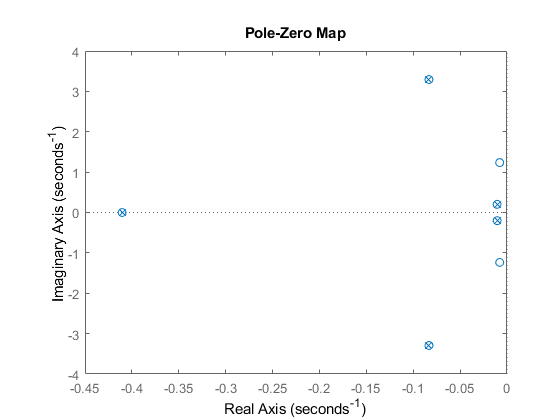

pzmap(G)

**Observations**

- No RHP poles

- No RHP zeros (?)

- Two complex pole pairs

- One real pole

- Three complex zero pairs

- One real zero

#### Question 3 

Design an appropriate $$W_{p_{11}}$$

For this we used the equation 3.81 from Skogestadt

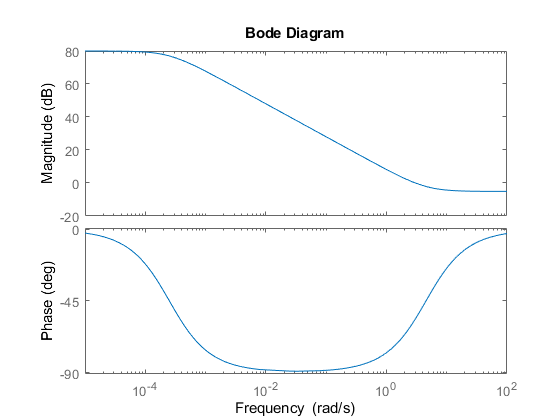

A = 1e-4;
omega_B = 0.4*2*pi;
M = 1.8;

Wp11 = (s/M + omega_B)/(s + omega_B*A);
Wp = [Wp11, 0; 0 0.2];
bode(Wp11)

#### Question 4/5

Build the generalized plant

% Controller sensitivity weight
Wu = [0.01 0; 0 tf([5e-3 7e-4 5e-5], [1 14e-4 1e-6])];

% Generalized plant
systemnames = 'G Wp Wu';
inputvar = '[w(2); [beta; tau_e]]';
input_to_G = '[beta; tau_e]';
input_to_Wu = '[beta; tau_e]';
input_to_Wp = '[w-G]';
outputvar = '[Wp; Wu; w-G]'; % Output generalized plant
sysoutname = 'P'; cleanupsysic = 'yes';
sysic; P = minreal(P, 1e-6, false)

P =
 
  From input "w(1)" to output...
              0.5556 s + 2.513
   [+Wp](1):  ----------------
               s + 0.0002513
 
   [+Wp](2):  0
 
   [+Wu](1):  0
 
   [+Wu](2):  0
 
   [+w-G](1):  1
 
   [+w-G](2):  0
 
  From input "w(2)" to output...
   [+Wp](1):  0
 
   [+Wp](2):  0.2
 
   [+Wu](1):  0
 
   [+Wu](2):  0
 
   [+w-G](1):  0
 
   [+w-G](2):  1
 
  From input "beta" to output...
                                                 
              0.04438 s^5 + 0.2026 s^4           
                                                 
                      + 0.4904 s^3 + 2.177 s^2   
                                                 
                           + 0.002893 s + 0.08691
                                                 
   [+Wp](1):  -----------------------------------
                                                 
              s^6 + 0.5982 s^5 + 10.98 s^4       
                                                 
                      + 4.712 s^3 + 0.5433 s^2  

#### Question 6/7

[K1, ~, gam, ~] = hinfsyn(P, 2, 2);
K1 = minreal(K1, 1e-6, false);
K2 = minreal(mixsyn(G, Wp, Wu, 0), 1e-6, false);

#### Question 8

Test the closed loop.

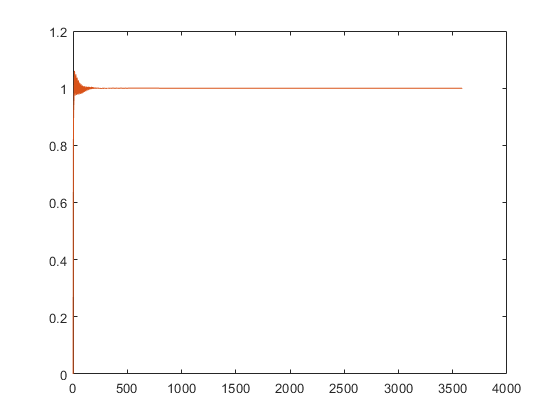

figure
CL1 = feedback(G*K1, eye(2), -1);
y1 = step(CL1);
plot(y1(:,1,1)); hold on;

CL2 = feedback(G*K2, eye(2), -1);
y2 = step(CL2);
plot(y2(:,1,1));


L = G*K2;
S = minreal(inv(eye(2) + L), [], false);

Nyquist plot

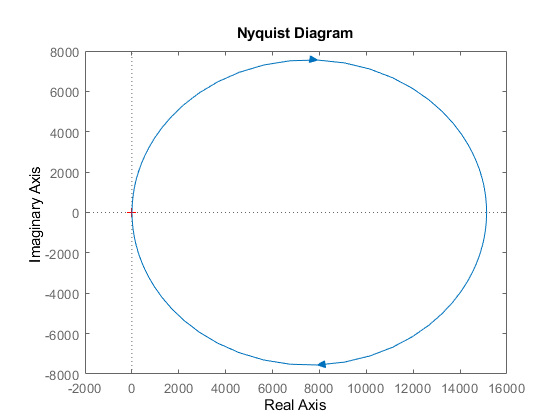

figure
gen_nyquist(L);

#### Question 9

Time domain simulations for both reference tracking and disturbance rejection.

Gd = G_MIMO(1,3);

### Part 2.1

Design new controller and error weights. The idea is that the controller for the torque $$\tau_e$$ reacts on the high-frequency disturbances and the controller for the pitch angle is sensitive to low-frequency () disturbances)

**Scale the plant**

G2 = G_MIMO(1,1:2);

SCALE_BETA = 20;     % degrees
SCALE_TORQUE = 5e3;  % Nm
SCALE_OUT = 1/90;   % rad/s

G2_scaled = SCALE_OUT*G2*diag([SCALE_BETA, SCALE_TORQUE]);

**Scale the disturbance dynamics**

SCALE_DIST = 2.5;
Gd_scaled = SCALE_OUT*Gd*SCALE_DIST;

**Build and tune the weights**

omega_LP = 2*pi/1000; % Tune roll-off
% omega_HP = 0.012;
omega_HP = 0.12*2*pi;
omega_B2 = 0.1*omega_LP;

Wu211 = tf(makeweight(1, [omega_LP, 2/sqrt(2)], 1e10));
Wu222 = tf(makeweight(1e10, [omega_HP, 2/sqrt(2)], 1));

Wp2 = (s/1.8 + omega_B2)/(s + omega_B2*1e4);

Wu2 = [Wu211 0; 0 Wu222];

**Connect the systems**

systemnames = 'G2_scaled Gd_scaled Wp2 Wu2';
inputvar = '[V; beta; tau_e]';

input_to_G2_scaled = '[beta; tau_e]';
input_to_Gd_scaled = '[V]';

input_to_Wp2 = '[-G2_scaled - Gd_scaled]';
input_to_Wu2 = '[beta; tau_e]';

outputvar = '[Wp2; Wu2; -G2_scaled - Gd_scaled]';
sysoutname = 'P2'; cleanupsysic = 'yes';
sysic;
P2 = minreal(P2, [], false);

**Compute the **$$H_\infty$
$**-controller **

[K3, ~, gam2, ~] = hinfsyn(P2, 1, 2);
disp(gam2)

    0.0013414



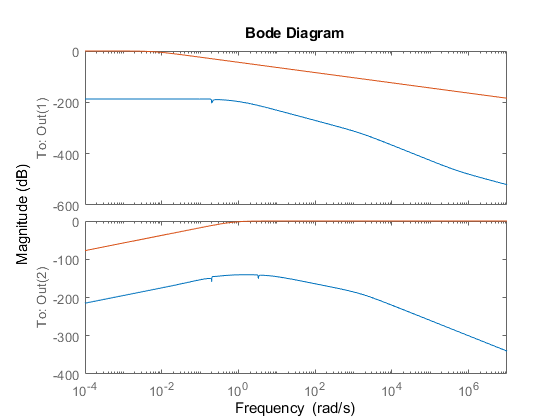

K3 = minreal(K3, 1e-6, false);

L2 = G2_scaled*K3;
S2 = inv(eye(size(L2, 1)) + L2);
T2 = eye(size(S2, 1)) - S2;

figure
bodemag(K3*S2*Gd_scaled); hold on;
bodemag([1/Wu211; 1/Wu222])

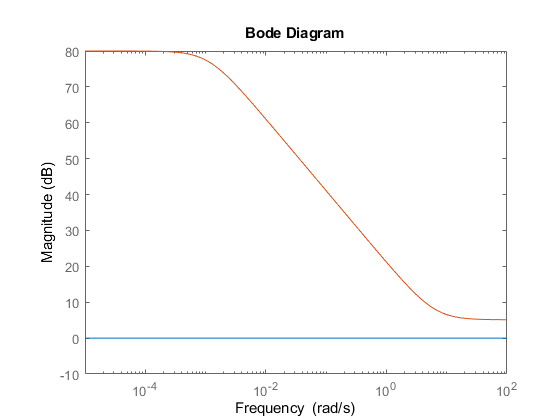


figure
bodemag(S2); hold on;
bodemag(1/Wp2)